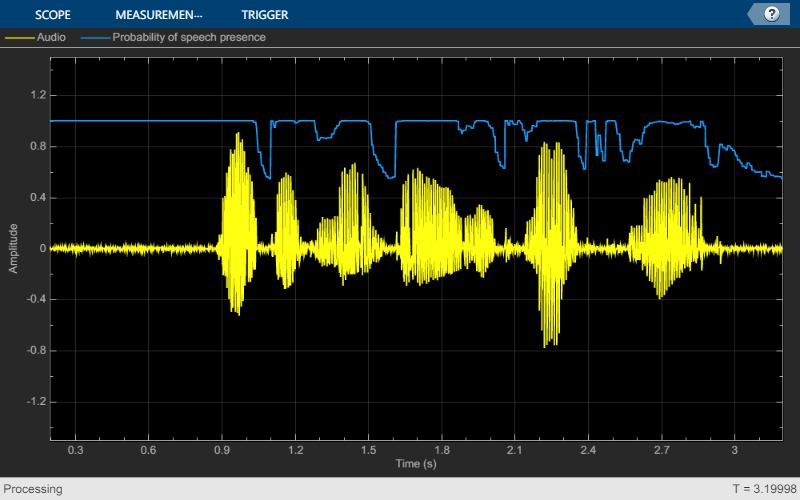

fileReader = dsp.AudioFileReader('C:\Users\ming\Desktop\matlab\tool\2.wav');
fs = fileReader.SampleRate;
fileReader.SamplesPerFrame = ceil(10e-3*fs);

VAD = voiceActivityDetector;

scope = timescope( ...
    'NumInputPorts',2, ...
    'SampleRate',fs, ...
    'TimeSpanSource','Property','TimeSpan',3, ...
    'BufferLength',3*fs, ...
    'YLimits',[-1.5 1.5], ...
    'TimeSpanOverrunAction','Scroll', ...
    'ShowLegend',true, ...
    'ChannelNames',{'Audio','Probability of speech presence'});
deviceWriter = audioDeviceWriter('SampleRate',fs);

while ~isDone(fileReader)
    audioIn = fileReader();
    probability = VAD(audioIn);
    scope(audioIn,probability*ones(fileReader.SamplesPerFrame,1))
    deviceWriter(audioIn);
end